## Assigment-Q9

#### Q9

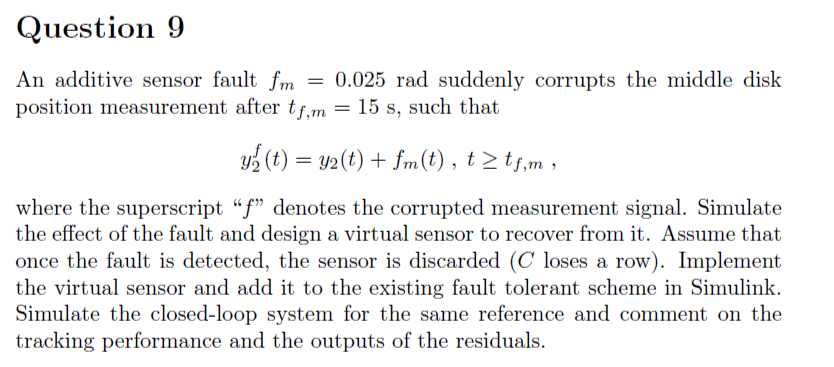


clear all
close all;
clc;
load('ECP_values.mat');
load('Q3_Q4.mat');
load('Q8.mat')
load('Q6.mat')

%Q8 data:

T_s=0.004;        %sampling period
d=0;            %no disturbances
theta_3_ref=pi/6; %reference: top disc tracks a reference, theta_3

% Physical system parameters
J_1 = 0.0025;                   % Disk 1 inertia kgm^2
J_2 = 0.0018;                   % Disk 2 inertia kgm^2
J_3 = 0.0018;                   % Disk 3 inertia kgm^2
k_1 = 2.7;                      % Shaft 1-2 stiffness Nm/rad
k_2 = 2.6;                      % Shaft 2-3 stiffness Nm/rad
b_1 = 0.0029;                   % Disk 1 damping and friction Nms/rad
b_2 = 0.0002;                   % Disk 2 damping and friction Nms/rad
b_3 = 0.00015;                  % Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s


%% State space representation
A = [0 1 0 0 0 0;
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0;
    0 0 0 1  0 0;
    k_1/J_2 0 (-k_1-k_2)/J_2 -b_2/J_2 k_2/J_2 0;
    0 0 0 0 0 1;
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 1/J_1 0 0 0 0]';
C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];
D = 0;
E_x = [0 -1/J_1 0 0 0 0]';
E_y = [0 0 0]';

%system discretization
sys_ss=ss(A,B,C,D);
sys_ssd=c2d(sys_ss,T_s);

F=sys_ssd.A;
G=sys_ssd.B;


%Simulation of the sensor y2 fault: f_m2=0.025 rad at t=15 s

f_m = [0;0.025;0];  
f_m_time = 15; 
sigma_meas = deg2rad(0.0056)*[1;1;1]; % Measurements noise

%simulation parameters
simTime=30;

%Filter parameters for the residuals:
wn=1;                           %natural frequency
zeta=0.96;                      %damping

%Dicrete virtual sensor design: 

%Check observability of the nominal system:

if (rank(obsv(F,C)) == size(F,1))
    disp('System is observable');
else
    disp('System is not observable');
end

System is observable



%discrete LQR observer design:

eig_CL_cont=(1/Ts)*log(eig_CL);
eig_CL_obsv=10*real(eig_CL_cont)+imag(eig_CL_cont)*j

eig_CL_obsv =   -7.7569 +64.9432i
  -7.7569 -64.9432i
 -27.0210 +35.5638i
 -27.0210 -35.5638i
 -82.6096 + 7.8722i
 -82.6096 - 7.8722i


eig_CL_obsv_d=exp(Ts*eig_CL_obsv)

eig_CL_obsv_d =    0.9369 + 0.2490i
   0.9369 - 0.2490i
   0.8885 + 0.1273i
   0.8885 - 0.1273i
   0.7183 + 0.0226i
   0.7183 - 0.0226i






L_d=place(F',C',eig_CL_obsv_d).';


%y2 fault:discard it and find Cf matrix

C_f=[ 1 0 0 0 0 0;
      0 0 0 0 1 0];
  
%Check the perfect static matching condition for sensor faults:

if (rank(C_f)==rank([C; C_f]))
    disp('Perfect static matching for sensor fault');
else
    disp('Imperfect static matching for sensor fault');
end

Imperfect static matching for sensor fault



%Check the observability of the faulty system

if (rank(obsv(A,C_f))==size(A,1))
    disp('Faulty system is observable');
else
    disp('Faulty system is not observable');
end

Faulty system is observable



%%Discrete virtual sensor design:

%discrete LQR observer design:




L_V_d=place(F',C_f',eig_CL_obsv_d).';
F_V = F-L_V_d*C_f;
G_V = G;
P_V_d = C*pinv(C_f);
C_V_d = C-P_V_d*C_f;


%Plot reference tracking when using virtual sensor:


ans_5=sim('Q9_Simulink');

outp=figure

outp =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


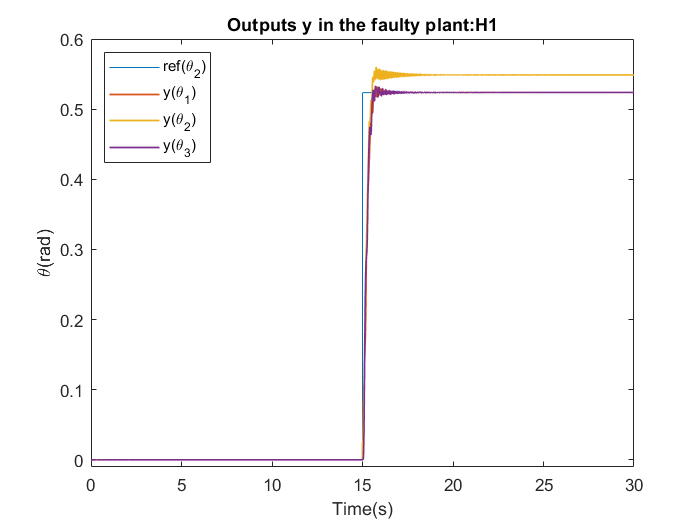

plot(ref.time,ref.signals.values)
hold on
plot(y.time,y.signals.values(:,1),'LineWidth',1)
hold on
plot(y.time,y.signals.values(:,2),'LineWidth',1)
hold on
plot(y.time,y.signals.values(:,3),'LineWidth',1)
title('Outputs y in the faulty plant:H1')
ylim([-0.01 0.6])
ylabel('\theta(rad)')
xlabel('Time(s)')
legend('ref(\theta_2)','y(\theta_1)','y(\theta_2)','y(\theta_3)','Location','northwest')
saveas(outp,'no-virt.png')

% figure
% plot(ref.time,ref.signals.values,yc.time,yc.signals.values(:,2))
% title('Output yc(\theta_2) in the virtual sensor:H1')
% ylabel('\theta_2(rad)')
% xlabel('Time(s)')
% legend('ref(\theta_2)','yc(\theta_2)')figure
virt=figure

virt =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


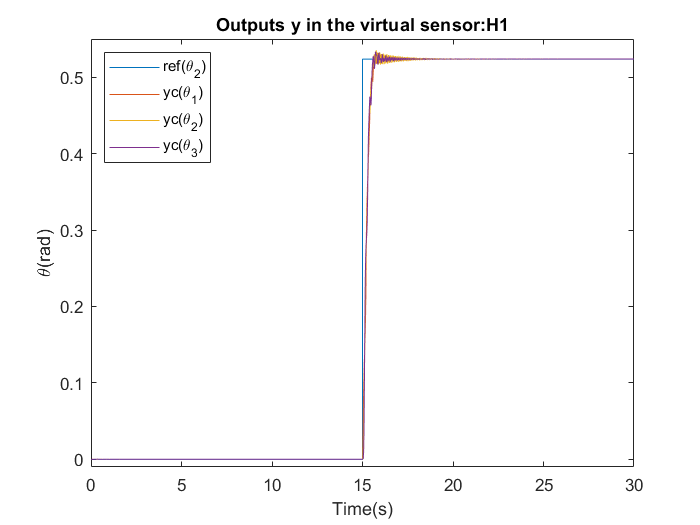

plot(ref.time,ref.signals.values)
hold on
plot(yc.time,yc.signals.values(:,1))
hold on
plot(yc.time,yc.signals.values(:,2))
hold on
plot(yc.time,yc.signals.values(:,3))
ylim([-0.01 0.55])
title('Outputs y in the virtual sensor:H1')
ylabel('\theta(rad)')
xlabel('Time(s)')
legend('ref(\theta_2)','yc(\theta_1)','yc(\theta_2)','yc(\theta_3)','Location','northwest')
saveas(virt,'virt.png')


res=figure

res =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


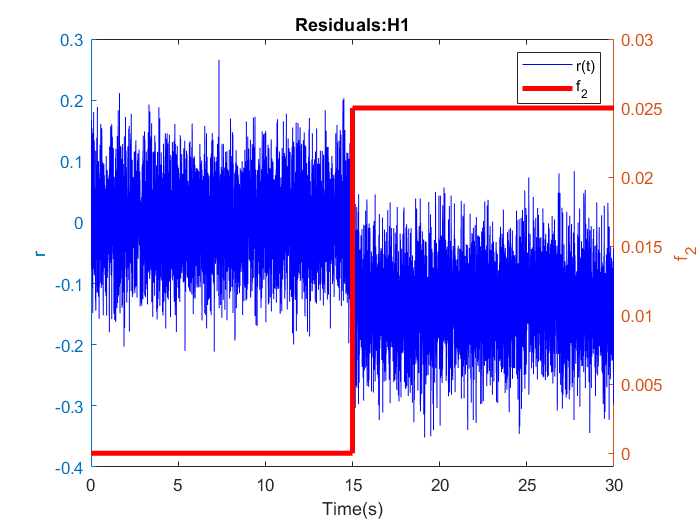

yyaxis right
plot(f_y.time,f_y.signals.values(:,2),'r','LineWidth',3)
ylabel('f_2')
ylim([-0.001 0.03])
hold on
yyaxis left
plot(r.time,r.signals.values,'b')
title('Residuals:H1')
ylabel('r')
xlabel('Time(s)')
legend('r(t)','f_2')
saveas(res,'Residual_q9.png')

action=figure

action =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


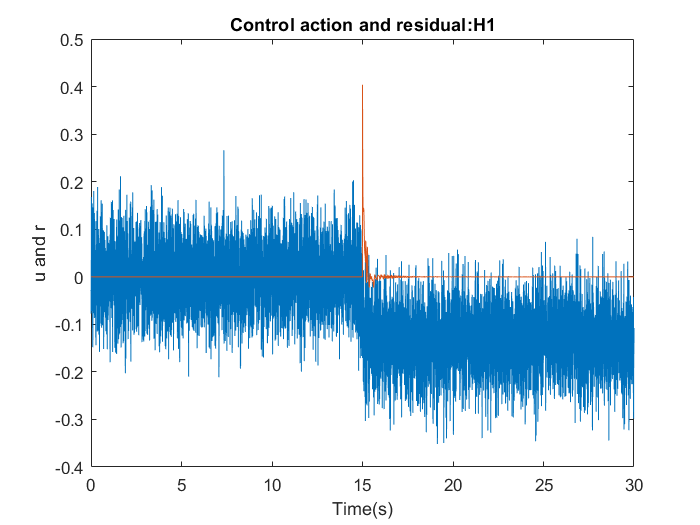

plot(r.time,r.signals.values)
hold on
plot(u.time,u.signals.values)
title('Control action and residual:H1')
ylabel('u and r')
xlabel('Time(s)')
saveas(action,'act.png')

# MISSING!!!

%%%EIG: MAS RAPIDOS QUE EN EL CL, LQR PERO CON UNA R CON VALORES MAS ALTOS,
%%%MAS RAPIDO


%%COGER EL SIMULINK GENERAL QUE TIENE EL CONTROLER, SISTEMA Y TAMBIEN LO
%%DEL VIRTUAL SENSOR